# **Edge Detection Techniques – Comparative Analysis**

clc;
clear;
close all;

Read the input image

img = imread('input_image.jpeg');

Display the original image

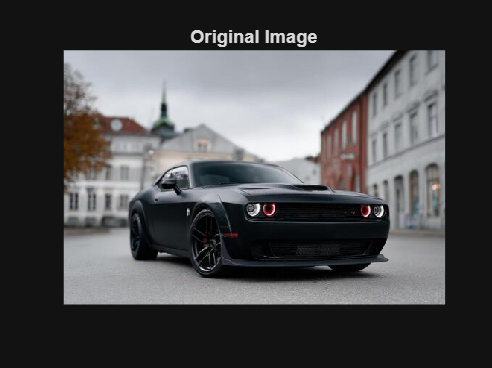

imshow(img);
title('Original Image');

## Grayscale Conversion

Convert the image to grayscale

gray_img = rgb2gray(img);

Display the grayscale image

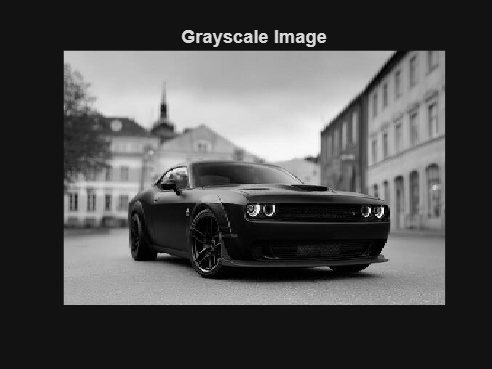

imshow(gray_img);
title('Grayscale Image');

## Noise Reduction

Apply Gaussian filter to reduce noise

filtered_img = imgaussfilt(gray_img, 1);

Display the filtered image

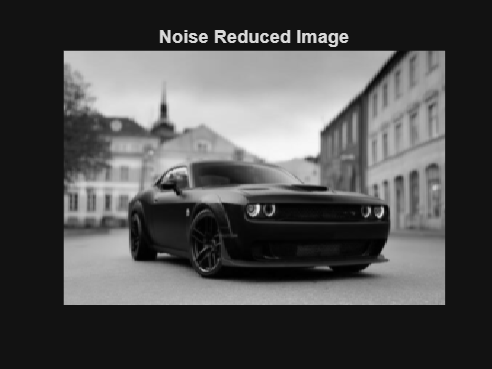

imshow(filtered_img);
title('Noise Reduced Image');

## Roberts Edge Detection

Apply Roberts edge detection

roberts_edges = edge(filtered_img, 'Roberts');

Display the result

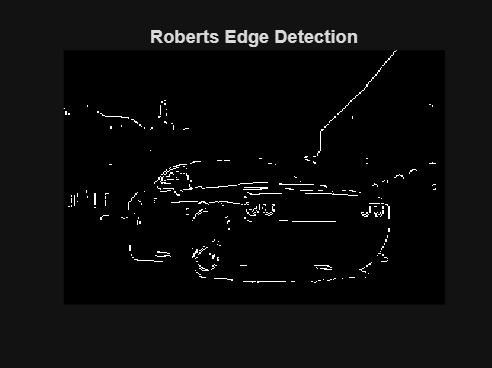

imshow(roberts_edges);
title('Roberts Edge Detection');

## Prewitt Edge Detection

Apply Prewitt edge detection

prewitt_edges = edge(filtered_img, 'Prewitt');

Display the result

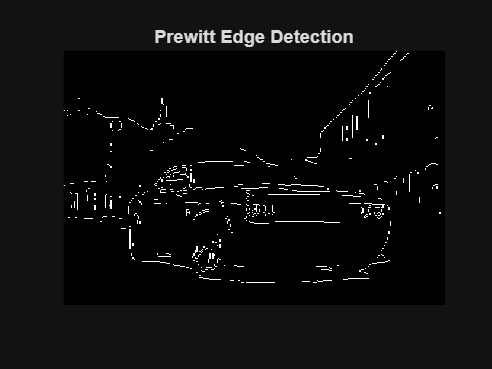

imshow(prewitt_edges);
title('Prewitt Edge Detection');

## Sobel Edge Detection

Apply Sobel edge detection

sobel_edges = edge(filtered_img, 'Sobel');

Display the result

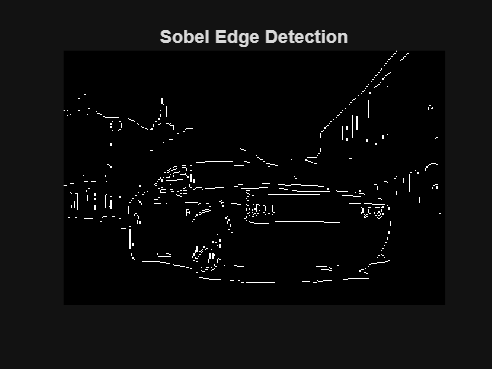

imshow(sobel_edges);
title('Sobel Edge Detection');

## Canny Edge Detection

Apply Canny edge detection

canny_edges = edge(filtered_img, 'Canny');

Display the result

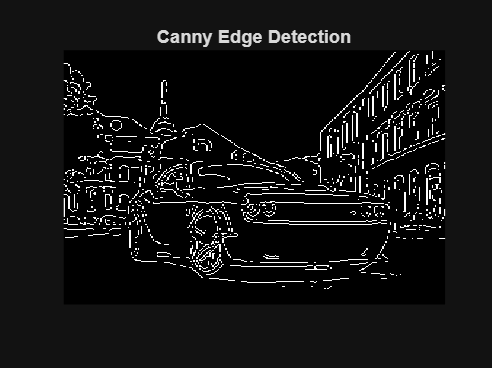

imshow(canny_edges);
title('Canny Edge Detection');

## Comparison of Edge Detection Methods

Display all edge detection results for comparison

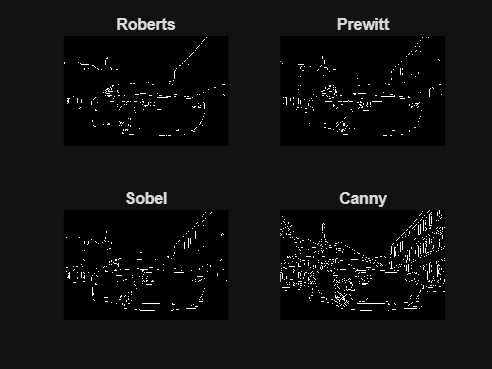

figure;

subplot(2,2,1);
imshow(roberts_edges);
title('Roberts');

subplot(2,2,2);
imshow(prewitt_edges);
title('Prewitt');

subplot(2,2,3);
imshow(sobel_edges);
title('Sobel');

subplot(2,2,4);
imshow(canny_edges);
title('Canny');